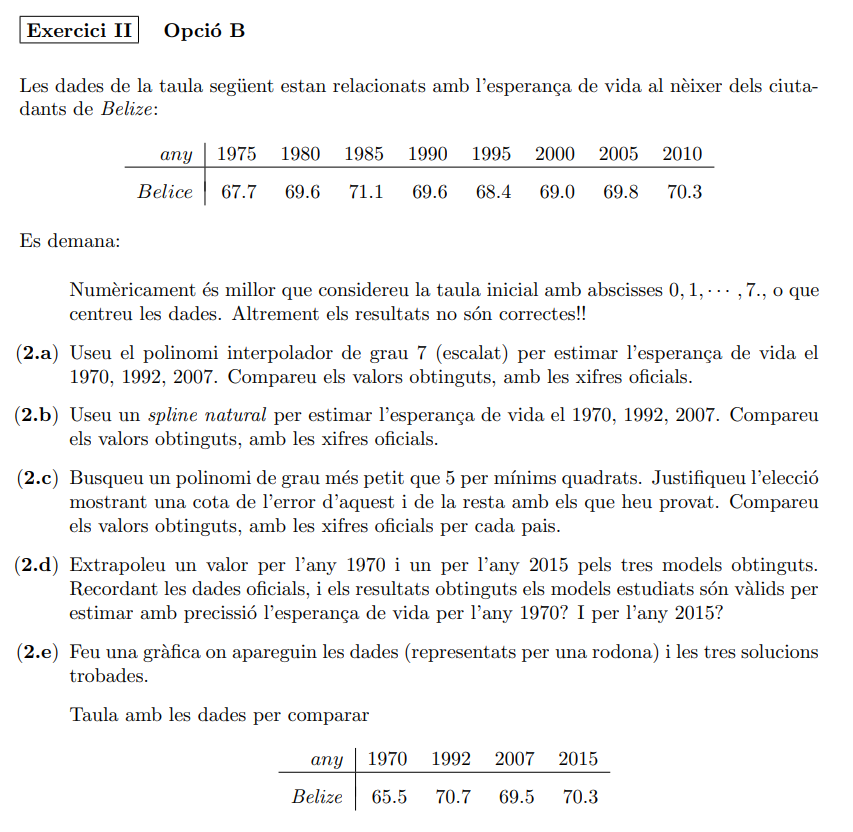

clear all
format shortG

real_x = [1975:5:2010];
x = [1:8]; % si 1970 es el 0, 1975 debe ser el 1, por eso la abcisa va de 1 a 8. Cada unidad equivale a 5 anyos.
y = [67.7 69.6 71.1 69.6 68.4 69.0 69.8 70.3];
P = polyfit(x,y,7);

% Apartado A

x0 = 1970; % valor donde pongo el 0
x1 = 1975; % valor donde pongo el 1
unit_value = (1/(x1 - x0)); % valor de una unidad (anyos) en puntos de la abcisa

newX = unit_value * ([1970 1992 2007 2015] - (x0.*ones(1,4))); % adaptamos los valores al rango
valor = [65.5 70.7 69.5 70.3];
aproximat = polyval(P,newX);
desviat = aproximat - valor;

Polinomio_interpolado = P;
ResA = array2table([valor; aproximat; desviat], 'VariableNames', {'1970', '1992', '2007', '2015'}, 'RowNames', {'valor', 'aproximat', 'desviat'});

% Apartado B

S = spline(x,y,newX);
ResB = array2table([valor; S; desviat], 'VariableNames', {'1970', '1992', '2007', '2015'}, 'RowNames', {'valor', 'spline', 'desviat'});

% Apartado C

poly1 = polyfit(x,y,1);
poly2 = polyfit(x,y,2);
poly3 = polyfit(x,y,3);
poly4 = polyfit(x,y,4);

dataC = [[1970:5:1990] 1992 [1995:5:2005] 2007 [2010:5:2015]];
dataC = unit_value * (dataC - (x0 .* ones(1,size(dataC,1))));
valorC = [65.5 67.7 69.6 71.1 69.6 70.7 68.4 69.0 69.8 69.5 70.3 70.3];

aprox1 = polyval(poly1,dataC);
aprox2 = polyval(poly2,dataC);
aprox3 = polyval(poly3,dataC);
aprox4 = polyval(poly4,dataC);

desv1 = abs(aprox1 - valorC);
desv2 = abs(aprox2 - valorC);
desv3 = abs(aprox3 - valorC);
desv4 = abs(aprox4 - valorC);

R1 = array2table([valorC; aprox1; desv1], 'RowNames', {'valor', 'aproximat', 'desviat'});
R2 = array2table([valorC; aprox2; desv2], 'RowNames', {'valor', 'aproximat', 'desviat'});
R3 = array2table([valorC; aprox3; desv3], 'RowNames', {'valor', 'aproximat', 'desviat'});
R4 = array2table([valorC; aprox4; desv4], 'RowNames', {'valor', 'aproximat', 'desviat'});

means = [mean(desv1),mean(desv2),mean(desv3),mean(desv4)]';
maximos = [max(desv1),max(desv2),max(desv3),max(desv4)]';
minimos = [min(desv1),min(desv2),min(desv3),min(desv4)]';

[~, id_min] = min(minimos);
[~, id_mean] = min(means);
[~, id_max] = min(maximos);

H = poly3;

% Apartado D

valorC = [65.5 70.3];
data = [1970, 2015];
data = unit_value * (data - (x0 .* ones(1,size(data,1))));

extra_poly7 = polyval(P,data);
extra_spline = spline(x,y,data);
extra_poly3 = polyval(H, data);

aproxC = [extra_poly7' extra_spline' extra_poly3']; % 



Res_1970 = array2table([valorC(1) * ones(1,3); aproxC(1,:); (aproxC(1,:) - valorC(1) * ones(1,3))], "VariableNames", {'poly7', 'spline', 'poly3'}, "RowNames", {'valor', 'aproximat', 'desviat'});
Res_2015 = array2table([valorC(2) * ones(1,3); aproxC(2,:); (aproxC(2,:) - valorC(2) * ones(1,3))], "VariableNames", {'poly7', 'spline', 'poly3'}, "RowNames", {'valor', 'aproximat', 'desviat'});

% Apartado E

dataE = [[1970:5:1990] 1992 [1995:5:2005] 2007 [2010:5:2015]];
% dataP = unit_value * (dataE - (x0 .* ones(1,size(dataE,1))));
dataP = [0:0.05:9];
dataPlot = linspace(1970,2015,size(dataP,2));
valorE = [65.5 67.7 69.6 71.1 69.6 70.7 68.4 69.0 69.8 69.5 70.3 70.3];

Pvalues = polyval(P,dataP);
Svalues = spline(x,y,dataP);
P2values = polyval(H,dataP);

## Resultados A

Polinomio_interpolado, ResA

Polinomio_interpolado =   -0.00017857     0.013889     -0.30833       3.1139      -16.088       42.222      -50.154         88.9


ResA = 3×4 table
                 1970     1992       2007      2015
                 ____    _______    _______    ____

    valor        65.5       70.7       69.5    70.3
    aproximat    88.9     68.918     69.851    79.9
    desviat      23.4    -1.7821    0.35056     9.6


## Resultados B

ResB

ResB = 3×4 table
                1970      1992       2007       2015 
               ______    _______    _______    ______

    valor        65.5       70.7       69.5      70.3
    spline     69.645     68.916     70.039    70.455
    desviat      23.4    -1.7821    0.35056       9.6


## Resultados C

id_min =      1


id_mean =      3


id_max =      2


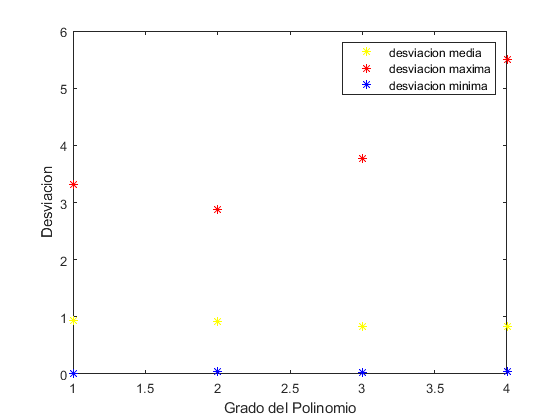

id_min, id_mean, id_max, plot([1:4],means,'*y',[1:4],maximos,'*r', [1:4], minimos,'*b'); xlabel('Grado del Polinomio'); ylabel("Desviacion"); legend('desviacion media', 'desviacion maxima', 'desviacion minima')

Para los 4 grados de polinomio interpolador estudiados, encontramos que el valor minimo de la desviacion media esta asociado al polinomio de grado 3. El valor minimo y maximo, cuentan con su menor error en polinomios diferentes, grado 1 y grado 2 respectivamente.

Por contar con un valor minimo muy cercano al minimo absoluto (de los datos utilizados) y contar tambien con el valor medio mas bajo, escojo el **polinomio de grado 3** entre los 4 estudiados (con los datos utilizados). 

## Resultados D

Res_1970, Res_2015

Res_1970 = 3×3 table
                 poly7    spline     poly3 
                 _____    ______    _______

    valor        65.5       65.5       65.5
    aproximat    88.9     69.645     63.936
    desviat      23.4     4.1455    -1.5643


Res_2015 = 3×3 table
                 poly7    spline     poly3 
                 _____    _______    ______

    valor        70.3        70.3      70.3
    aproximat    79.9      70.455    74.064
    desviat       9.6     0.15455    3.7643


## Resultados E

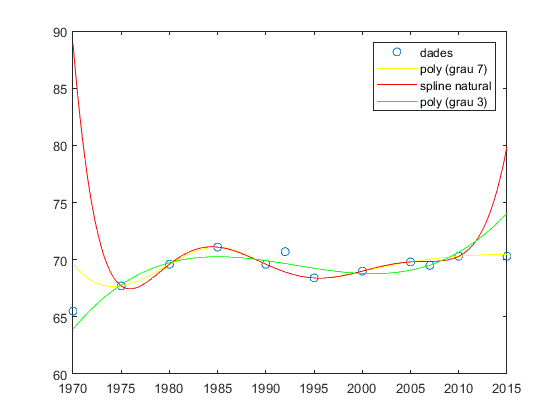

plot(dataE,valorE,'o',dataPlot,Svalues,'-y',dataPlot,Pvalues,'-r' ,dataPlot,P2values,'-g');
legend('dades', 'poly (grau 7)', 'spline natural', 'poly (grau 3)');